syms u c t
assume(u, {'real', 'positive'})
assume(c, {'real', 'positive'})
assume(t, {'real', 'positive'})

u = c * t;
ri = 4*(0.396*cos(2.65*(u+1.4)));
rj = 4*(-0.99*sin(u+1.4));
r = [ri rj 0];

u_nums = linspace(0, 3.2, 100);
r_outs = zeros(length(u_nums), 3);

for i=1:length(u_nums)
    r_outs(i, :) = double(subs(r, [u], [u_nums(i)]));
end

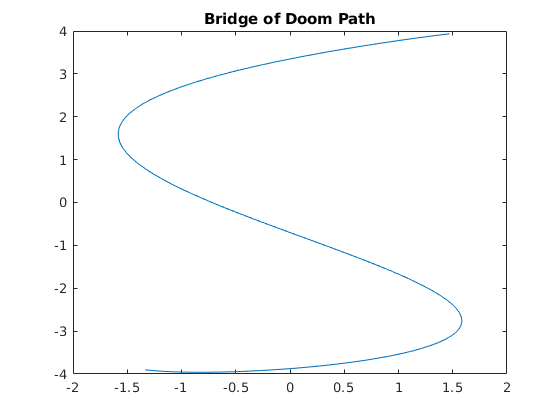

% Plot bridge of doom path
clf
plot(r_outs(:, 1), r_outs(:, 2))
title('Bridge of Doom Path')

% Compute left and right velocities
vel = diff(r, t);
T = simplify(vel ./ norm(vel));
dT = diff(T, t);
w = simplify(cross(T, dT));
V_T = simplify(dot(T, vel));

syms d
assume(d, {'real', 'positive'})

V_L = simplify(V_T - w(3) * d / 2);
V_R = simplify(V_T + w(3) * d / 2);

d_num = 0.235;
c_num = 1/3;
vl_num = zeros(size(u_nums, 1));
vr_num = zeros(size(u_nums, 1));
t_nums = u_nums / c_num;

for n=1:length(u_nums)
    vl_num(n) = double(subs(V_L,[u, d, c],[u_nums(n), d_num, c_num]));
    vr_num(n) = double(subs(V_R,[u, d, c],[u_nums(n), d_num, c_num]));
end

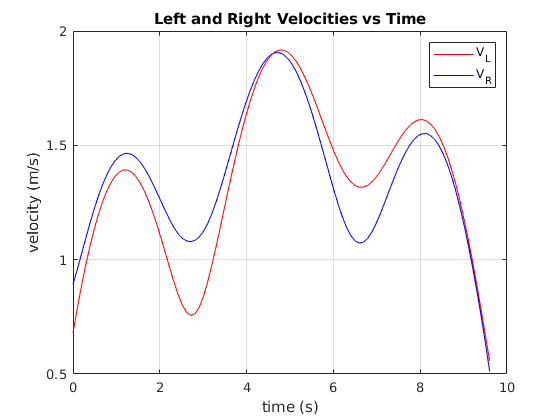

clf
plot(t_nums, vl_num, 'r', t_nums, vr_num, 'b')
title('Left and Right Velocities vs Time')
xlabel('time (s)')
ylabel('velocity (m/s)')
legend('V_L', 'V_R')
grid on

% Compute linear speed and angular velocity
w_num = zeros(size(u_nums, 1));
vt_num = zeros(size(u_nums, 1));

for n=1:length(u_nums)
    tmp_w = double(subs(w,[u, c],[u_nums(n), c_num]));
    w_num(n) = tmp_w(3);
    vt_num(n) = double(subs(V_T,[u, c],[u_nums(n), c_num]));
end

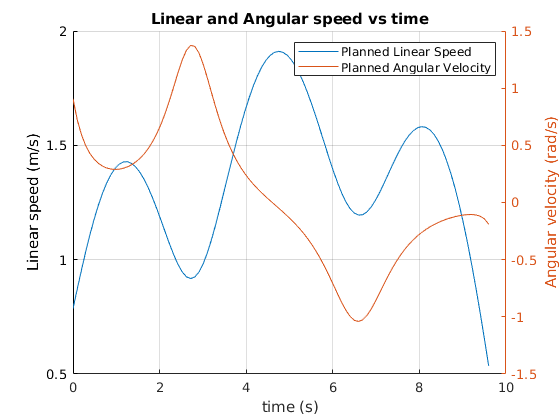

clf
hold on
plot(t_nums, vt_num)
xlabel('time (s)')
ylabel('Linear speed (m/s)')

yyaxis right

plot(t_nums, w_num)
xlabel('time (s)')
ylabel('Angular velocity (rad/s)')

title('Linear and Angular speed vs time')
legend('Planned Linear Speed', 'Planned Angular Velocity')
grid on
hold off

load('data/b.mat')

dataset = dataset(12:90, :);

% Dataset row format
% [timestamp, positionLeft, positionRight, AccelX, AccelY, AccelZ];
mV_L = diff(dataset(:, 2)) ./ diff(dataset(:, 1));
mV_R = diff(dataset(:, 3)) ./ diff(dataset(:, 1));
time = dataset(2:end, 1) - dataset(2, 1);

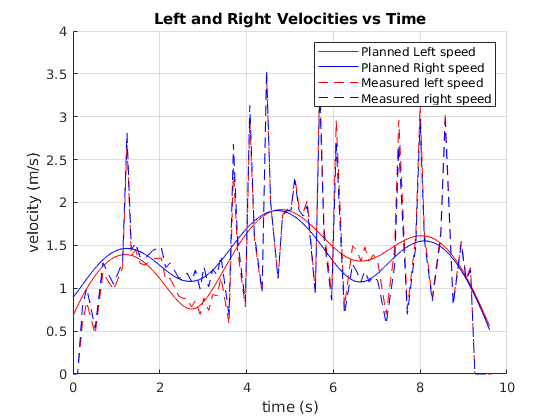

clf
hold on
plot(t_nums, vl_num, 'r', t_nums, vr_num, 'b')
plot(time, mV_L, 'r--', time, mV_R, 'b--')
title('Left and Right Velocities vs Time')
xlabel('time (s)')
ylabel('velocity (m/s)')
legend('Planned Left speed', 'Planned Right speed', 'Measured left speed', 'Measured right speed')
grid on
hold off

mV_T = (mV_L + mV_R) / 2;
mw = (mV_R - mV_L) / d_num;

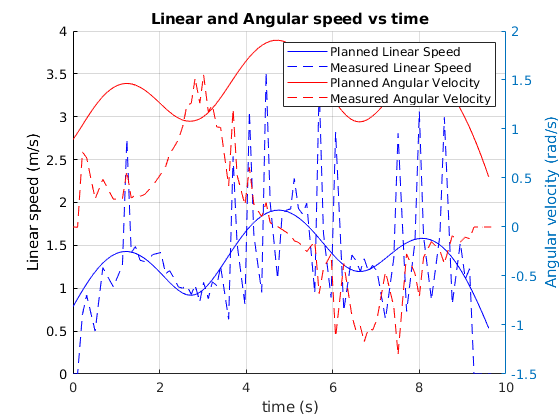

clf
hold on
plot(t_nums, vt_num, 'b', time, mV_T, 'b--');
xlabel('time (s)')
ylabel('Linear speed (m/s)')

yyaxis right
plot(t_nums, vr_num, 'r', time, mw, 'r--')
xlabel('time (s)')
ylabel('Angular velocity (rad/s)')

title('Linear and Angular speed vs time')
legend('Planned Linear Speed', 'Measured Linear Speed', 'Planned Angular Velocity', 'Measured Angular Velocity')
grid on
hold off